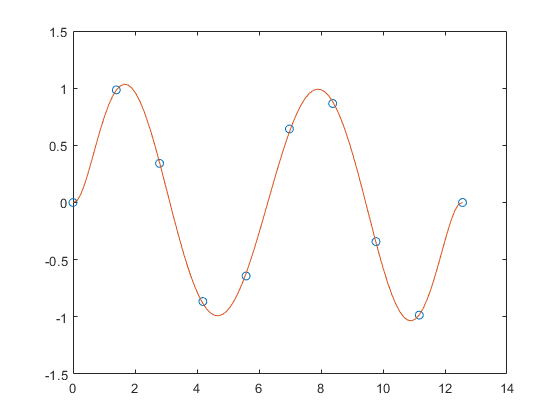

x = linspace(0,4*pi,10);
y = sin(x);

k = 7;
p = polyfitOrtho(x,y,k);

x1 = linspace(0,4*pi);
y1 = polyvalOrtho(p,x1);
figure
plot(x,y,'o')
hold on
plot(x1,y1)
hold off

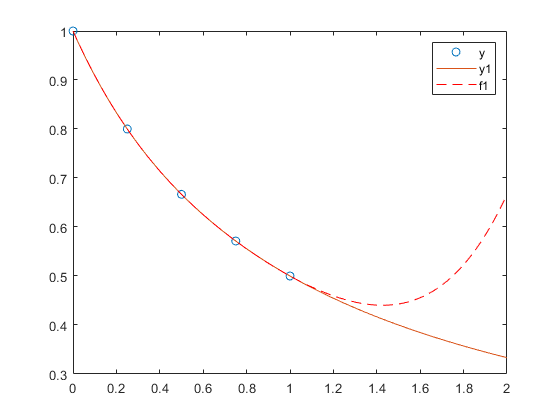

x = linspace(0,1,5);
y = 1./(1+x);

k = 4;
p = polyfitOrtho(x,y,k);

x1 = linspace(0,2);
y1 = 1./(1+x1);
f1 = polyvalOrtho(p,x1);

figure
plot(x,y,'o')
hold on
plot(x1,y1)
plot(x1,f1,'r--')
legend('y','y1','f1')

x = (0:0.1:2.5)';
y = erf(x);

k = 6;
p = polyfitOrtho(x,y,6);


f = polyvalOrtho(p,x);
T = table(x,y,f,y-f,'VariableNames',{'X','Y','Fit','FitError'})

T = 26×4 table
     X        Y          Fit         FitError  
    ___    _______    __________    ___________

      0          0    0.00044117    -0.00044117
    0.1    0.11246       0.11185     0.00060836
    0.2     0.2227       0.22231     0.00039189
    0.3    0.32863       0.32872    -9.7429e-05
    0.4    0.42839        0.4288    -0.00040661
    0.5     0.5205       0.52093    -0.00042568
    0.6    0.60386       0.60408    -0.00022824
    0.7     0.6778       0.67775     4.6383e-05
    0.8     0.7421       0.74183     0.00026992
    0.9    0.79691       0.79654     0.00036515
      1     0.8427       0.84238      0.0003164
    1.1    0.88021       0.88005     0.00015948
    1.2    0.91031       0.91035    -3.9919e-05
    1.3    0.93401       0.93422      -0.000211
    1.4    0.95229       0.95258    -0.00029933
    1.5    0.96611       0.96639

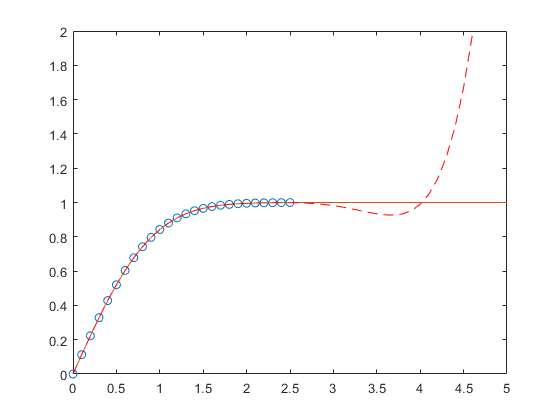


x1 = (0:0.1:5)';
y1 = erf(x1);
f1 = polyvalOrtho(p,x1);
figure
plot(x,y,'o')
hold on
plot(x1,y1,'-')
plot(x1,f1,'r--')
axis([0  5  0  2])
hold off

year = (1750:25:2000)';
pop = 1e6*[791 856 978 1050 1262 1544 1650 2532 6122 8170 11560]';
T = table(year, pop)

T = 11×2 table
    year       pop   
    ____    _________

    1750     7.91e+08
    1775     8.56e+08
    1800     9.78e+08
    1825     1.05e+09
    1850    1.262e+09
    1875    1.544e+09
    1900     1.65e+09
    1925    2.532e+09
    1950    6.122e+09
    1975     8.17e+09
    2000    1.156e+10


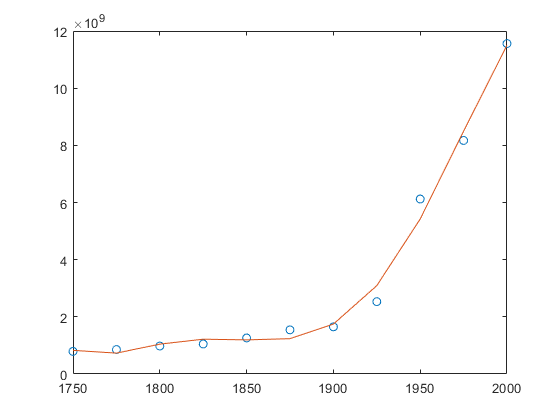


plot(year,pop,'o')

[p] = polyfitOrtho(T.year, T.pop, 5);

f = polyvalOrtho(p,year);
hold on
plot(year,f)
hold off